clear 
clc

wt = [101, 249, 499] / 1024;
Fs = 100E6;
Fin = wt .* Fs;
C1 = 38.72E-12;
V0 = 0.895;
Ron0 = 6.5;
L = [0.2, 0.4, 0.6,0.8, 1, 2, 3];
alpha = [-1.15, -0.15, 0.15, 0.3, 0.4, 0.6, 0.68];

for i = 1:length(alpha)
    temp = getHD_new(Ron0, V0, C1, Fin, alpha(i));
    TXT = ['L = ', num2str(L(i)), 'um, alpha = ', ...
        num2str(alpha(i)), ';'];
    disp(TXT)
    HD3 = reshape(temp(1,2,:),1,3)
    HD3S = SD_Exchange_Simplified(Ron0, V0, C1, Fin, alpha(i))

end

L = 0.2um, alpha = -1.15;


HD3 =   -88.7710  -73.2874  -61.5322


HD3S =   -88.6397  -72.9646  -60.8885


L = 0.4um, alpha = -0.15;


HD3 =   -94.1284  -78.5319  -66.5880


HD3S =   -94.0745  -78.3994  -66.3234


L = 0.6um, alpha = 0.15;


HD3 =   -96.7406  -81.1246  -69.1480


HD3S =   -96.7001  -81.0250  -68.9489


L = 0.8um, alpha = 0.3;


HD3 =   -98.4255  -82.8074  -70.8275


HD3S =   -98.3865  -82.7114  -70.6354


L = 1um, alpha = 0.4;


HD3 =   -99.7672  -84.1532  -72.1802


HD3S =   -99.7255  -84.0503  -71.9743


L = 2um, alpha = 0.6;


HD3 =  -103.3136  -87.7361  -75.8260


HD3S =  -103.2473  -87.5722  -75.4961


L = 3um, alpha = 0.68;


HD3 =  -105.2774  -89.7380  -77.8944


HD3S =  -105.1855  -89.5104  -77.4343


## Fin vs. HD3

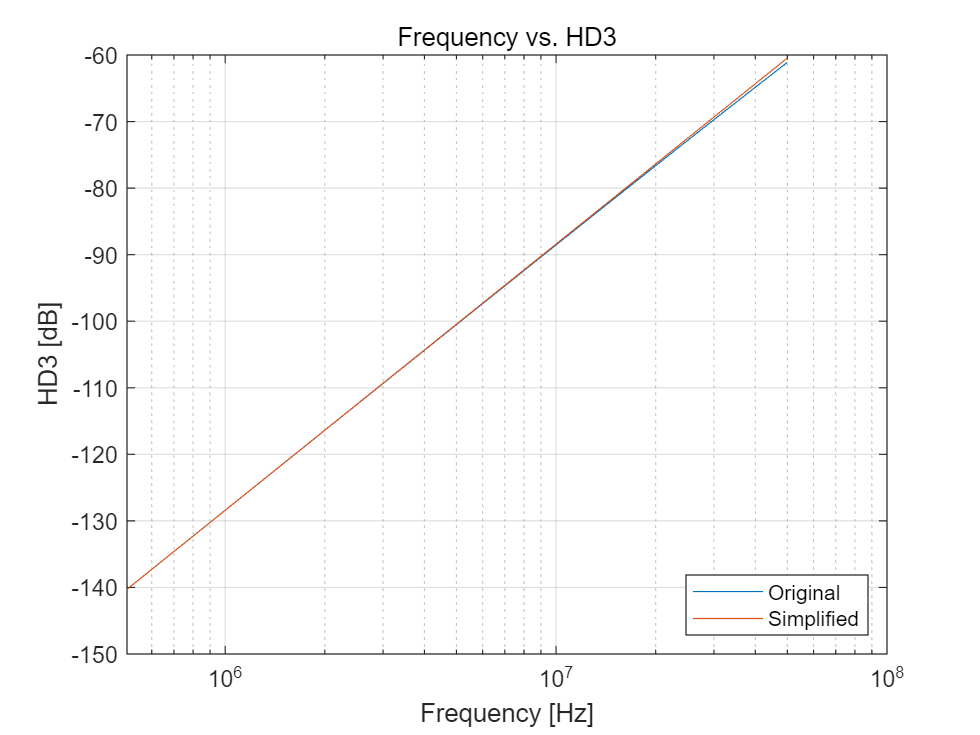

fin = linspace(0,0.5,100) * Fs;
temp = getHD_new(Ron0, V0, C1, fin, alpha(1));
HD3_fin = reshape(temp(1,2,:), 1, length(fin));
HD3S_fin = SD_Exchange_Simplified(Ron0, V0, C1, fin, alpha(1));

figure
semilogx(fin, [HD3_fin; HD3S_fin]);
box on;
grid on;
xlabel("Frequency [Hz]");
ylabel("HD3 [dB]");
legend(["Original", "Simplified"], 'Location','southeast')
title("Frequency vs. HD3")

## Ron vs. HD3

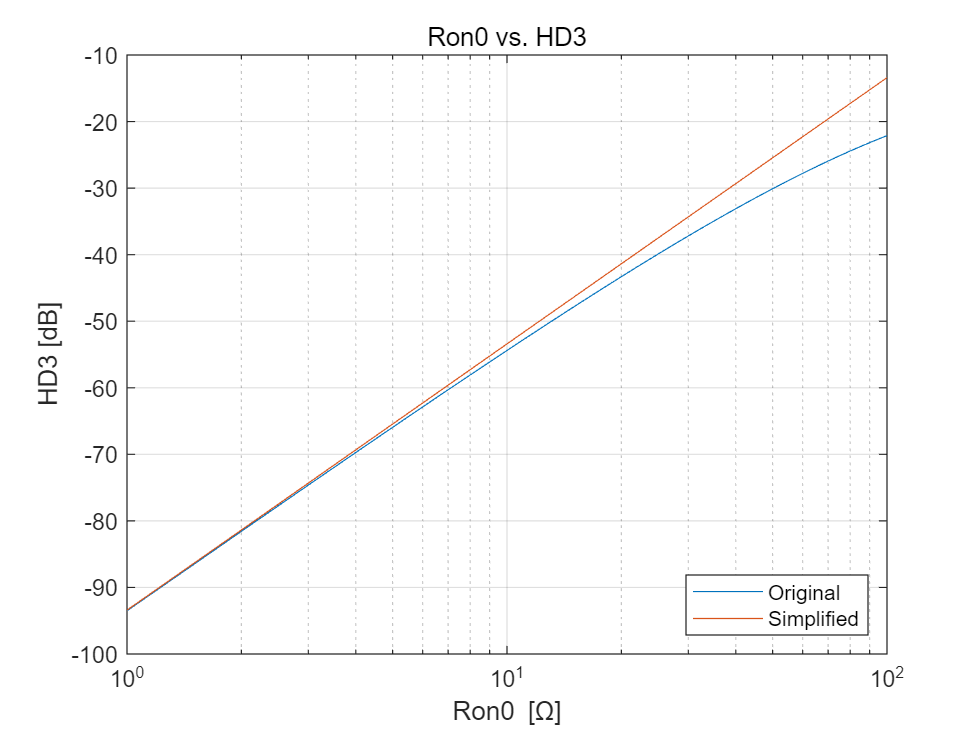

ron = linspace(1,100);
FIN = Fin(3);
temp = getHD_new(ron, V0, C1, FIN, alpha(1));
HD3_ron = reshape(temp(:,2), 1, length(ron));
HD3S_ron = SD_Exchange_Simplified(ron, V0, C1, FIN, alpha(1));

figure
semilogx(ron, [HD3_ron; HD3S_ron]);
box on;
grid on;
xlabel("Ron0 [\Omega]");
ylabel("HD3 [dB]");
legend(["Original", "Simplified"], 'Location','southeast')
title("Ron0 vs. HD3")

## CL vs HD3

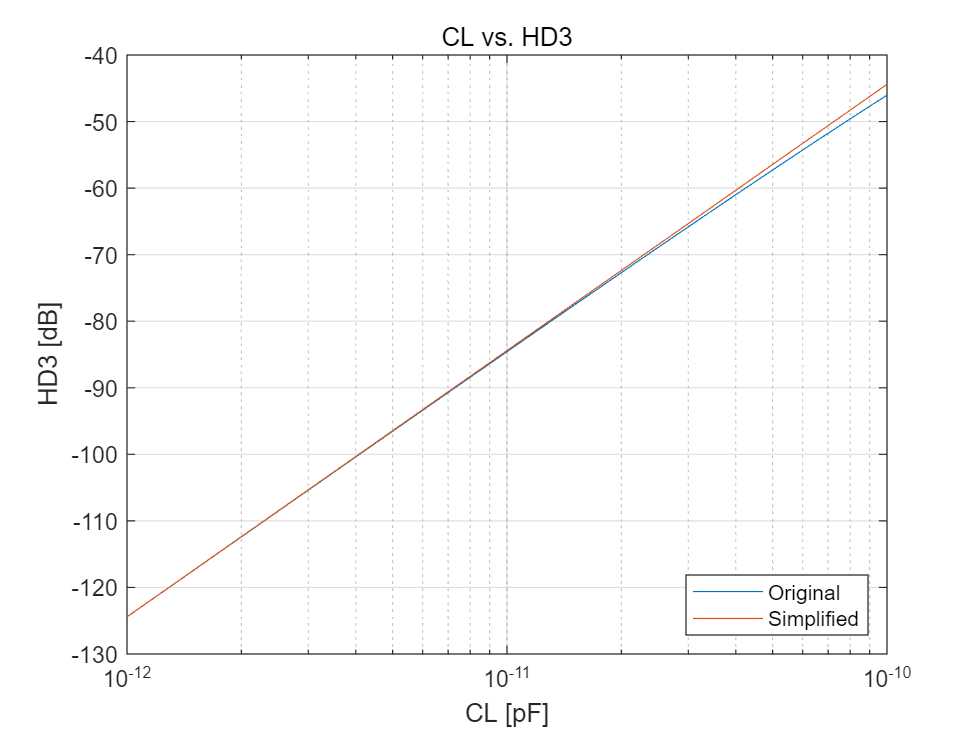

cl = linspace(1,100).*1E-12;
FIN = Fin(3);
HD3_cl = zeros(1,length(cl));
for i = 1:length(cl)
    temp = getHD_new(Ron0, V0, cl(i), FIN, alpha(1));
    HD3_cl(i) = temp(2);
end

HD3S_cl = SD_Exchange_Simplified(Ron0, V0, cl, FIN, alpha(1));

figure
semilogx(cl, [HD3_cl; HD3S_cl]);
box on;
grid on;
xlabel("CL [pF]");
ylabel("HD3 [dB]");
legend(["Original", "Simplified"], 'Location','southeast')
title("CL vs. HD3")

## V0 vs HD3

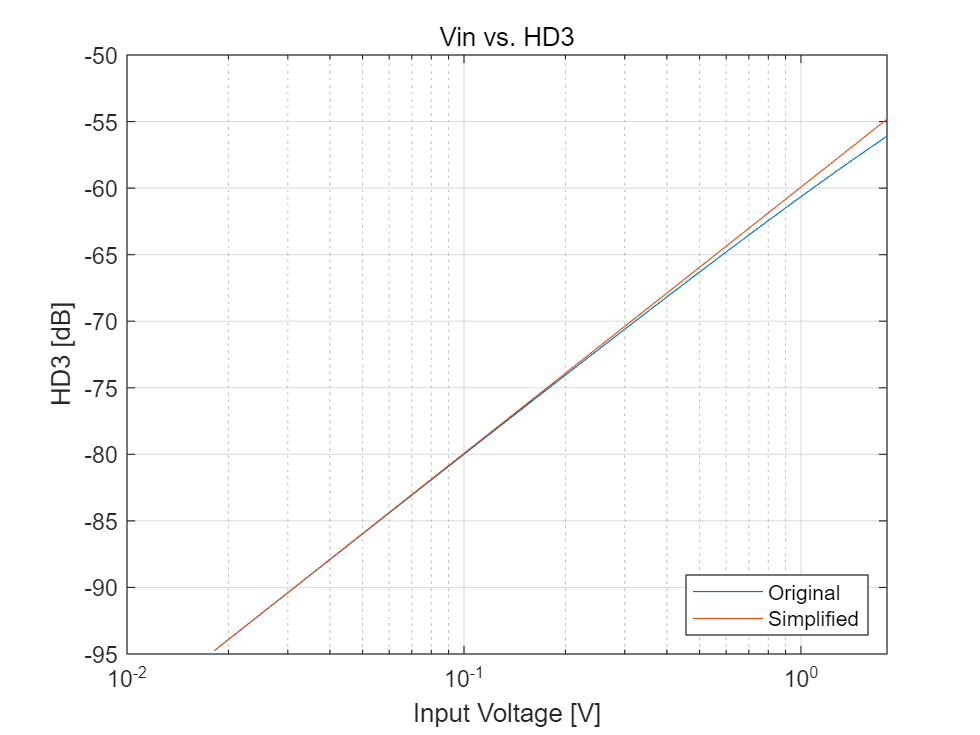

v0 = linspace(0,1.8);
FIN = Fin(3);
HD3_v0 = zeros(1,length(v0));
HD3S_v0 = zeros(1,length(v0));

for i = 1:length(v0)
    temp = getHD_new(Ron0, v0(i), C1, FIN, alpha(1));
    HD3_v0(i) = temp(2);
    HD3S_v0(i) = SD_Exchange_Simplified(Ron0, v0(i), C1, FIN, alpha(1));
end

figure
semilogx(v0, [HD3_v0; HD3S_v0]);
box on;
grid on;
xlabel("Input Voltage [V]");
ylabel("HD3 [dB]");
legend(["Original", "Simplified"], 'Location','southeast')
title("Vin vs. HD3")

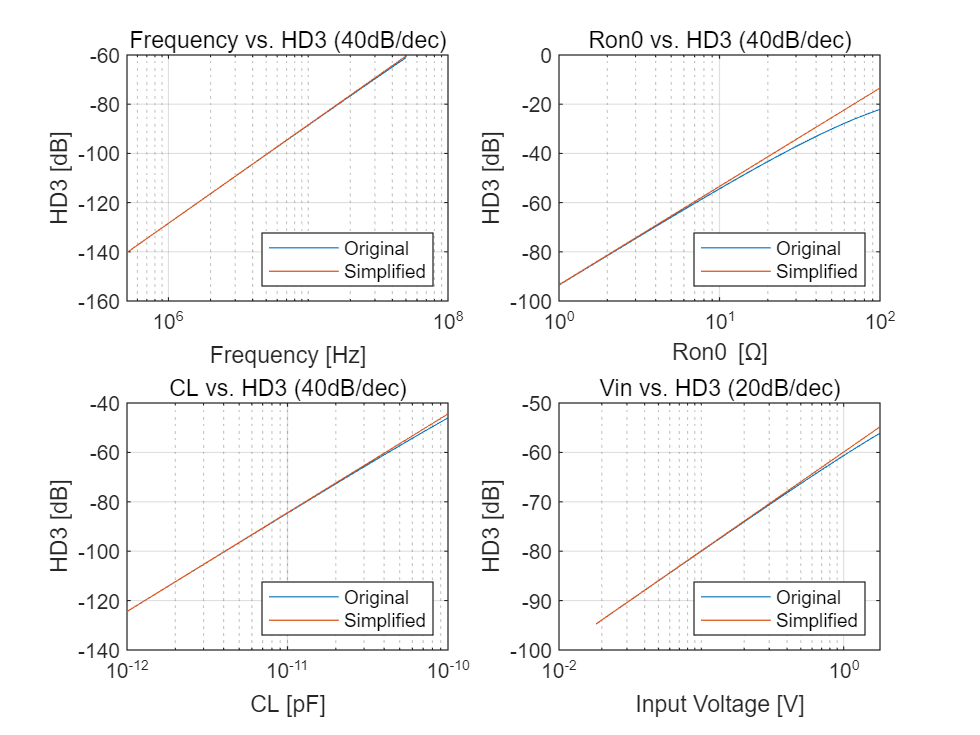

figure
subplot(2,2,1)
semilogx(fin, [HD3_fin; HD3S_fin]);
box on;
grid on;
xlabel("Frequency [Hz]");
ylabel("HD3 [dB]");
legend(["Original", "Simplified"], 'Location','southeast')
title("Frequency vs. HD3 (40dB/dec)")

subplot(2,2,2)
semilogx(ron, [HD3_ron; HD3S_ron]);
box on;
grid on;
xlabel("Ron0 [\Omega]");
ylabel("HD3 [dB]");
legend(["Original", "Simplified"], 'Location','southeast')
title("Ron0 vs. HD3 (40dB/dec)")

subplot(2,2,3)
semilogx(cl, [HD3_cl; HD3S_cl]);
box on;
grid on;
xlabel("CL [pF]");
ylabel("HD3 [dB]");
legend(["Original", "Simplified"], 'Location','southeast')
title("CL vs. HD3 (40dB/dec)")

subplot(2,2,4)
semilogx(v0, [HD3_v0; HD3S_v0]);
box on;
grid on;
xlabel("Input Voltage [V]");
ylabel("HD3 [dB]");
legend(["Original", "Simplified"], 'Location','southeast')
title("Vin vs. HD3 (20dB/dec)")